|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance | DistanceWeig-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ht           |
|====================================================================================================================|
|    1 | Best   |    -0.76494 |     0.22238 |    -0.76494 |    -0.76494 |           48 |  correlation |      inverse |
|    2 | Best   |    -0.76657 |     0.27426 |    -0.76657 |    -0.76615 |           23 |    euclidean |      inverse |
|    3 | Best   |    -0.77853 |     0.31628 |    -0.77853 |    -0.77763 |           11 |    chebychev |        equal |
|    4 | Accept |    -0.73064 |     0.24568 |    -0.77853 |    -0.77733 |            4 |    chebychev | squaredinver |
|    5 | Accept |    -0.77704 |     0.32558 |   

|  692 | Accept |    -0.80056 |     0.30003 |    -0.80056 |     -0.7994 |           31 |    cityblock |        equal |
|  693 | Accept |    -0.79703 |     0.31119 |    -0.80056 |    -0.79882 |           33 |    cityblock |        equal |
|  694 | Accept |     -0.7934 |     0.17695 |    -0.80056 |    -0.79886 |           37 |  correlation |        equal |
|  695 | Accept |    -0.76361 |     0.38016 |    -0.80056 |    -0.79888 |           30 |    chebychev |      inverse |
|  696 | Accept |    -0.76923 |     0.26642 |    -0.80056 |    -0.79913 |           21 |    cityblock |      inverse |
|  697 | Accept |    -0.76502 |     0.42904 |    -0.80056 |    -0.79902 |           44 |    chebychev |      inverse |
|  698 | Accept |    -0.80056 |     0.28405 |    -0.80056 |    -0.79881 |           31 |    cityblock |        equal |
|  699 | Accept |    -0.76461 |     0.41498 |    -0.80056 |    -0.79934 |           40 |    chebychev |      inverse |
|  700 | Accept |    -0.80056 |     0.27875 |   

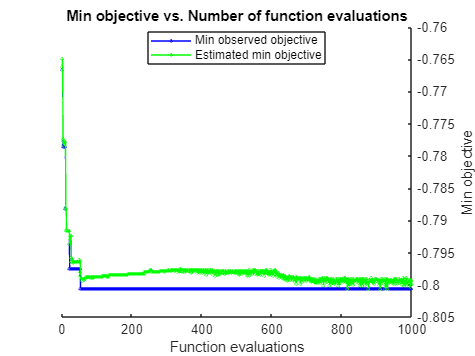

Mejores Hiperparámetros:


Número de Vecinos: 31


Distancia: cityblock


Peso de Distancia: equal


Mejor F1 Score: 0.80056


Métricas de Rendimiento:


Precisión: 0.76719


Recall: 0.83697


F1 Score: 0.80056


Matriz de Confusión:


        1182         606
         389        1997



% Script de Optimización Bayesiana para KNN con Maximización de F1 Score


% Paso 1: Preparación de datos
data = readtable('nac2015.csv'); % Cargar archivo CSV
data_cauca = data(data.COD_DPTO == 20, :); % Filtrar por departamento con COD_DPTO == 20
data = data_cauca; % Ajustar la variable de trabajo

% Asegurarnos que FECHA_NACM sea del tipo fecha
data.FECHA_NACM = datetime(data.FECHA_NACM, 'InputFormat', 'dd/MM/yyyy');

% Paso 2: Seleccionar las columnas de interés
X = data(:, {'AREANAC', 'PESO_NAC', 'TALLA_NAC', 'T_GES', 'NUMCONSUL', ...
'TIPO_PARTO', 'EDAD_MADRE', 'EST_CIVM', 'IDPERTET', 'NIV_EDUM'});

% Eliminar filas con valores faltantes (NaN)
X = rmmissing(X);
y = data.N_HIJOSV >= 2; % Etiqueta: 1 si tiene más de un hijo, 0 si no.

% Preprocesamiento: Normalización de características
X_norm = normalize(X, 'scale');

% Conversión a matriz numérica
X_numeric = table2array(X_norm);

% División de datos: Entrenamiento y Prueba
cv = cvpartition(y, 'HoldOut', 0.3);
X_train = X_numeric(training(cv), :);
y_train = y(training(cv));
X_test = X_numeric(test(cv), :);
y_test = y(test(cv));

% Definición de la función objetivo para Bayesian Optimization
objective = @(x) optimizeKNN(x, X_train, y_train, X_test, y_test);

% Especificación de los hiperparámetros a optimizar
hp_space = [
    optimizableVariable('NumNeighbors', [1, 50], 'Type', 'integer')
    optimizableVariable('Distance', {'euclidean', 'cityblock', 'chebychev', 'correlation'}, 'Type', 'categorical')
    optimizableVariable('DistanceWeight', {'equal', 'inverse', 'squaredinverse'}, 'Type', 'categorical')
];

% Realizar Bayesian Optimization
results = bayesopt(objective, hp_space, ...
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'MaxObjectiveEvaluations', 1000);

% Recuperar los mejores hiperparámetros
best_params = results.XAtMinObjective;

% Convertir hiperparámetros
best_num_neighbors = round(best_params.NumNeighbors);
best_distance = char(best_params.Distance);
best_distance_weight = char(best_params.DistanceWeight);

% Imprimir resultados de la optimización
disp('Mejores Hiperparámetros:');
disp(['Número de Vecinos: ', num2str(best_num_neighbors)]);
disp(['Distancia: ', best_distance]);
disp(['Peso de Distancia: ', best_distance_weight]);
disp(['Mejor F1 Score: ', num2str(-results.MinObjective)]);

% Entrenar modelo final con mejores hiperparámetros
final_knn = fitcknn(X_train, y_train, ...
    'NumNeighbors', best_num_neighbors, ...
    'Distance', best_distance, ...
    'DistanceWeight', best_distance_weight);

% Predecir y evaluar
y_pred = predict(final_knn, X_test);

% Calcular métricas manualmente
TP = sum((y_test == 1) & (y_pred == 1));
FP = sum((y_test == 0) & (y_pred == 1));
FN = sum((y_test == 1) & (y_pred == 0));

% Calcular Precisión, Recall y F1 Score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Imprimir métricas detalladas
disp('Métricas de Rendimiento:');
disp(['Precisión: ', num2str(precision)]);
disp(['Recall: ', num2str(recall)]);
disp(['F1 Score: ', num2str(f1_score)]);

% Matriz de Confusión
confusion_matrix = confusionmat(y_test, y_pred);
disp('Matriz de Confusión:');
disp(confusion_matrix);

% Función de optimización de KNN
function neg_f1 = optimizeKNN(params, X_train, y_train, X_test, y_test)
    % Convertir parámetros categóricos a caracteres
    distance = char(params.Distance);
    dist_weight = char(params.DistanceWeight);
    
    % Entrenar modelo KNN con parámetros actuales
    knn_model = fitcknn(X_train, y_train, ...
        'NumNeighbors', round(params.NumNeighbors), ...
        'Distance', distance, ...
        'DistanceWeight', dist_weight);
    
    % Predecir en conjunto de prueba
    y_pred = predict(knn_model, X_test);
    
    % Calcular F1 Score manualmente
    TP = sum((y_test == 1) & (y_pred == 1));
    FP = sum((y_test == 0) & (y_pred == 1));
    FN = sum((y_test == 1) & (y_pred == 0));
    
    precision = TP / (TP + FP);
    recall = TP / (TP + FN);
    
    % Calcular F1 Score
    if precision + recall > 0
        f1 = 2 * (precision * recall) / (precision + recall);
    else
        f1 = 0;
    end
    
    % Devolver negativo para minimización
    neg_f1 = -f1;
end